# Experiment 8

This Live Script contains the experimental setup described in the section: *"3.4. Experiments and results", *included in the dissertation:

W. González-Vanegas,** "Planning Methodologies for the Operation and Expansion of Distribution Systems Considering the Interactions with the Transmission System"**, Ph.D. dissertation, Dept. of Elect. Electron. and Comp. Eng., National University of Colombia, Manizales, Caldas, 2025.

*Note: MATLAB R2023a is the oldest version where this Live Script was successfully tested. *

Configure the hybrid case to be analyzed by filling variables `T_case, D_case, bus_T, `and `bus_D,` according to the following table:

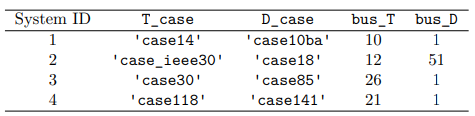

T_case = 'case30';
D_case = 'case85';
bus_T = 26;
bus_D = 1;

Initialization:

define_constants;    % MATPOWER column indices
rng(10);             % Fix seed for random number generator

Case-specific commands:

mpc_T = loadcase(T_case);
mpc_D = loadcase(D_case);
hybrid_case = [T_case '-' D_case];
id_bus_T = find(mpc_T.bus(:,BUS_I) == bus_T);
id_bus_D = find(mpc_D.bus(:,BUS_I) == bus_D);
switch hybrid_case    
    case 'case14-case10ba'    % Buses are 10(T) & 1(D)        
        mpc_T.bus(:,BASE_KV) = 138;
        id_branch_bus_D = find(mpc_D.branch(:,F_BUS) == id_bus_D);  % Activate the tap parameter for the first branch(es)
        mpc_D.branch(id_branch_bus_D,TAP) = 1;
    case 'case_ieee30-case18' % Buses are 12(T) & 51(D)
        mpc_D.bus(id_bus_D,BASE_KV) = mpc_T.bus(id_bus_T,BASE_KV);
        mpc_D.bus(id_bus_D-1,BASE_KV) = mpc_T.bus(id_bus_T,BASE_KV);
    case 'case30-case85'      % Buses are 26(T) & 1(D)
        id_branch_bus_D = find(mpc_D.branch(:,F_BUS) == id_bus_D);  % Activate the tap parameter for the first branch(es)
        mpc_D.branch(id_branch_bus_D,TAP) = 1;
    case 'case118-case141'    % Buses are 21(T) & 1(D)
        id_branch_bus_D = find(mpc_D.branch(:,F_BUS) == id_bus_D);  % Activate the tap parameter for the first branch(es)
        mpc_D.branch(id_branch_bus_D,TAP) = 1;    
end

Plot the single-line diagram of the networks being connected. The nomenclature is as follows:

- Red circles: nodes with demand

- Green circles: nodes with generation

- Brown circles: nodes with generation and demand

- Purple hexagram: buses that are connected to form a T-D Interface

- Blue edges: branchs with transformers

wgv.case_utils.plot_TD_sld(mpc_T,mpc_D,bus_T,bus_D,1)

Look for generator(s) connected to the distribution side of the TD interface  and remove them

id_gen_bus_D = find(mpc_D.gen(:,GEN_BUS)==bus_D);
if id_gen_bus_D
    mpc_D.gen(id_gen_bus_D,:) = [];
    mpc_D.bus(id_bus_D,BUS_TYPE) = PQ;
end
mpc_D_aux = mpc_D;

Remove initial demand of bus_T in the transmission network as the distribution network is itself the new demand

mpc_T.bus(bus_T,PD) = 0;
mpc_T.bus(bus_T,QD) = 0;

Run a power flow for the transmission network to get a good starting point, including the equality of voltages at the TD interface

mpc_T = runpf(mpc_T,mpoption('out.all',0,'verbose',0));
mpc_D.bus(id_bus_D,VM) = mpc_T.bus(id_bus_T,VM);
mpc_D.bus(id_bus_D,VA) = mpc_T.bus(id_bus_T,VA);

Ensure equal base voltages at both sides of the TD interface:

mpc_D.bus(id_bus_D,BASE_KV) = mpc_T.bus(id_bus_T,BASE_KV);

Connect cases to create a hybrid network with single-phase tranmission and three-phase distribution descriptions

[mpc_hybrid,conn_hybrid_info] = wgv.case_utils.connect_cases(mpc_T,mpc_D,bus_T,bus_D,1);

Unbalance the disribution network changing the load and line parameters:

mpc_hybrid = wgv.case_utils.unbalance_case(mpc_hybrid,{'line_params','load'});

Define options and run power flows with LTPC, QTPC, and AC formulations

res_ac_hybrid = run_pf(mpc_hybrid,mpoption('out.gen',1),'mpx',mp.xt_3p);

mpopt_qtpc = mpoption('model','TPC','out.gen',1);
mpopt_qtpc.pf.tpc.form = 'QUAD';
mpc_hybrid.bus3p(:,[7 8 9]) = 0;
res_qtpc_hybrid = run_pf(mpc_hybrid,mpopt_qtpc,'mpx',wgv.xt_tpc_3p);
mpopt_ltpc = mpopt_qtpc;
mpopt_ltpc.pf.tpc.form = 'LIN';
res_ltpc_hybrid = run_pf(mpc_hybrid,mpopt_ltpc,'mpx',wgv.xt_tpc_3p);

Now, we explore the differences in the results of the power flow when compared to the case of a three-phase model for the whole system

mpc_D_aux.bus(id_bus_D,BASE_KV) = mpc_T.bus(id_bus_T,BASE_KV);
mpc_D_aux.branch(1,TAP) = 1;
if isfield(mpc_T,'bus_name')
    mpc_T = rmfield(mpc_T,'bus_name');
end
if isfield(mpc_T,'order')
    mpc_T = rmfield(mpc_T,'order');
end

[mpc_TD,connect_info_1p] = wgv.case_utils.connect_cases(mpc_T,mpc_D,bus_T,bus_D);
mpc3p_TD = mp.case_utils.convert_1p_to_3p(mpc_TD);
connect_info_3p = wgv.case_utils.from_1p_to_3p_connect_info(connect_info_1p,mpc_TD,mpc3p_TD);
nload1p = length(find(mpc_T.bus(:,PD)+mpc_T.bus(:,QD)));
nline1p = length(find(mpc_T.branch(:,TAP)==0));
mpc3p_TD.load3p(nload1p+1:end,4:9) = mpc_hybrid.load3p(:,4:9);
mpc3p_TD.lc(nline1p+1:end,2:end) = mpc_hybrid.lc(:,2:end);

Run three-phase power flow

res_ac_3p = run_pf(mpc3p_TD,mpoption('out.gen',1),'mpx',mp.xt_3p);
mpc3p_TD.bus3p(:,[7 8 9]) = 0;
res_qtpc_3p = run_pf(mpc3p_TD,mpopt_qtpc,'mpx',wgv.xt_tpc_3p);
res_ltpc_3p = run_pf(mpc3p_TD,mpopt_ltpc,'mpx',wgv.xt_tpc_3p);

Finally, some comparisons:

- We compare the results of the hybrid network vs. the results of the three-phase network with the AC formulation:

    % Extract results of hybrid network
    nb1p = size(mpc_hybrid.bus,1);
    va_ac_hybrid_1p = res_ac_hybrid.dm.elements.bus.tab.va + repmat([0 -120 120],nb1p,1);
    vm_ac_hybrid_1p = repmat(res_ac_hybrid.dm.elements.bus.tab.vm,1,3);
    id_bus_3p = setdiff(mpc_hybrid.bus3p(:,1),bus_D);
    [~,id_bus_3p] = ismember(id_bus_3p,mpc_hybrid.bus3p(:,1));
    va_ac_hybrid_3p = table2array(res_ac_hybrid.dm.elements.bus3p.tab(id_bus_3p,["va1","va2","va3"]));
    vm_ac_hybrid_3p = table2array(res_ac_hybrid.dm.elements.bus3p.tab(id_bus_3p,["vm1","vm2","vm3"]));
    va_ac_hybrid = [va_ac_hybrid_1p; va_ac_hybrid_3p];
    vm_ac_hybrid = [vm_ac_hybrid_1p; vm_ac_hybrid_3p];
    p_interface_ac_hybrid = table2array(res_ac_hybrid.dm.elements.buslink.tab(:,["pg1_start","pg2_start","pg3_start"])); 
    q_interface_ac_hybrid = table2array(res_ac_hybrid.dm.elements.buslink.tab(:,["qg1_start","qg2_start","qg3_start"])); 
    
    % Extract results of three-phase network
    va_ac_3p = table2array(res_ac_3p.dm.elements.bus3p.tab(:,["va1","va2","va3"]));
    vm_ac_3p = table2array(res_ac_3p.dm.elements.bus3p.tab(:,["vm1","vm2","vm3"]));
    ninter = numel(connect_info_3p.interface.fname);
    p_interface_ac_3p = zeros(ninter,3);
    q_interface_ac_3p = zeros(ninter,3);
    for i = ninter
        fname = connect_info_3p.interface.fname{i};
        idx = connect_info_3p.interface.idx{i};
        if res_ac_3p.dm.elements.(fname).tab.bus_fr(idx) == bus_T
            sign = 1;
        elseif res_ac_3p.dm.elements.(fname).tab.bus_to(idx) == bus_T
            sign = -1;
        else
            error('ex_8_TD_Interface: something went wrong when identiying branch links in three-phase results');
        end
        p_interface_ac_3p(i,:) = sign*table2array(res_ac_3p.dm.elements.(fname).tab(idx,["pl1_fr","pl2_fr","pl3_fr"]));
        q_interface_ac_3p(i,:) = sign*table2array(res_ac_3p.dm.elements.(fname).tab(idx,["ql1_fr","ql2_fr","ql3_fr"]));
    end
    
    % Compute error metrics
    nv = size(vm_ac_hybrid,1);
    rmse_va_ac = 1/sqrt(nv) * vecnorm(va_ac_hybrid - va_ac_3p);
    rmse_vm_ac = 1/sqrt(nv) * vecnorm(vm_ac_hybrid - vm_ac_3p);
    pre_p_interface_ac = abs(p_interface_ac_hybrid - p_interface_ac_3p) ./ abs(p_interface_ac_3p) * 100;
    pre_q_interface_ac = abs(q_interface_ac_hybrid - q_interface_ac_3p) ./ abs(q_interface_ac_3p) * 100;
    
    results_ac = table({hybrid_case},rmse_va_ac(1),rmse_va_ac(2),rmse_va_ac(3), ...
        rmse_vm_ac(1),rmse_vm_ac(2),rmse_vm_ac(3), ...
        pre_p_interface_ac(1),pre_p_interface_ac(2),pre_p_interface_ac(3), ...
        pre_q_interface_ac(1),pre_q_interface_ac(2),pre_q_interface_ac(3));
    
    results_ac.Properties.VariableNames = {
        'Case','RMSE(Va,a) deg','RMSE(Va,b) deg','RMSE(Va,c) deg', ...
               'RMSE(Vm,a) p.u.','RMSE(Vm,b) p.u.','RMSE(Vm,c) p.u.', ...
               'RE(P,a) %','RE(P,b) %','RE(P,c) %', ...
               'RE(Q,a) %','RE(Q,b) %','RE(Q,c) %'}

- Besides, we compare the results using the QTPC formulation:

    % Extract results of hybrid network
    nb1p = size(mpc_hybrid.bus,1);
    va_qtpc_hybrid_1p = res_qtpc_hybrid.dm.elements.bus.tab.va + repmat([0 -120 120],nb1p,1);
    vm_qtpc_hybrid_1p = repmat(res_qtpc_hybrid.dm.elements.bus.tab.vm,1,3);
    id_bus_3p = setdiff(mpc_hybrid.bus3p(:,1),bus_D);
    [~,id_bus_3p] = ismember(id_bus_3p,mpc_hybrid.bus3p(:,1));
    va_qtpc_hybrid_3p = table2array(res_qtpc_hybrid.dm.elements.bus3p.tab(id_bus_3p,["va1","va2","va3"]));
    vm_qtpc_hybrid_3p = table2array(res_qtpc_hybrid.dm.elements.bus3p.tab(id_bus_3p,["vm1","vm2","vm3"]));
    va_qtpc_hybrid = [va_qtpc_hybrid_1p; va_qtpc_hybrid_3p];
    vm_qtpc_hybrid = [vm_qtpc_hybrid_1p; vm_qtpc_hybrid_3p];
    p_interface_qtpc_hybrid = table2array(res_qtpc_hybrid.dm.elements.buslink.tab(:,["pg1_start","pg2_start","pg3_start"])); 
    q_interface_qtpc_hybrid = table2array(res_qtpc_hybrid.dm.elements.buslink.tab(:,["qg1_start","qg2_start","qg3_start"])); 
    
    % Extract results of three-phase network
    va_qtpc_3p = table2array(res_qtpc_3p.dm.elements.bus3p.tab(:,["va1","va2","va3"]));
    vm_qtpc_3p = table2array(res_qtpc_3p.dm.elements.bus3p.tab(:,["vm1","vm2","vm3"]));
    ninter = numel(connect_info_3p.interface.fname);
    p_interface_qtpc_3p = zeros(ninter,3);
    q_interface_qtpc_3p = zeros(ninter,3);
    for i = ninter
        fname = connect_info_3p.interface.fname{i};
        idx = connect_info_3p.interface.idx{i};
        if res_qtpc_3p.dm.elements.(fname).tab.bus_fr(idx) == bus_T
            sign = 1;
        elseif res_qtpc_3p.dm.elements.(fname).tab.bus_to(idx) == bus_T
            sign = -1;
        else
            error('ex_8_TD_Interface: something went wrong when identiying branch links in three-phase results');
        end
        p_interface_qtpc_3p(i,:) = sign*table2array(res_qtpc_3p.dm.elements.(fname).tab(idx,["pl1_fr","pl2_fr","pl3_fr"]));
        q_interface_qtpc_3p(i,:) = sign*table2array(res_qtpc_3p.dm.elements.(fname).tab(idx,["ql1_fr","ql2_fr","ql3_fr"]));
    end
    
    % Compute error metrics
    nv = size(vm_qtpc_hybrid,1);
    rmse_va_qtpc = 1/sqrt(nv) * vecnorm(va_qtpc_hybrid - va_qtpc_3p);
    rmse_vm_qtpc = 1/sqrt(nv) * vecnorm(vm_qtpc_hybrid - vm_qtpc_3p);
    pre_p_interface_qtpc = abs(p_interface_qtpc_hybrid - p_interface_qtpc_3p) ./ abs(p_interface_qtpc_3p) * 100;
    pre_q_interface_qtpc = abs(q_interface_qtpc_hybrid - q_interface_qtpc_3p) ./ abs(q_interface_qtpc_3p) * 100;
    
    results_qtpc = table({hybrid_case},rmse_va_qtpc(1),rmse_va_qtpc(2),rmse_va_qtpc(3), ...
        rmse_vm_qtpc(1),rmse_vm_qtpc(2),rmse_vm_qtpc(3), ...
        pre_p_interface_qtpc(1),pre_p_interface_qtpc(2),pre_p_interface_qtpc(3), ...
        pre_q_interface_qtpc(1),pre_q_interface_qtpc(2),pre_q_interface_qtpc(3));
    
    results_qtpc.Properties.VariableNames = {
        'Case','RMSE(Va,a) deg','RMSE(Va,b) deg','RMSE(Va,c) deg', ...
               'RMSE(Vm,a) p.u.','RMSE(Vm,b) p.u.','RMSE(Vm,c) p.u.', ...
               'RE(P,a) %','RE(P,b) %','RE(P,c) %', ...
               'RE(Q,a) %','RE(Q,b) %','RE(Q,c) %'}

- And, finally, we compare the results with the LTPC formulation:

    % Extract results of hybrid network
    nb1p = size(mpc_hybrid.bus,1);
    va_ltpc_hybrid_1p = res_ltpc_hybrid.dm.elements.bus.tab.va + repmat([0 -120 120],nb1p,1);
    vm_ltpc_hybrid_1p = repmat(res_ltpc_hybrid.dm.elements.bus.tab.vm,1,3);
    id_bus_3p = setdiff(mpc_hybrid.bus3p(:,1),bus_D);
    [~,id_bus_3p] = ismember(id_bus_3p,mpc_hybrid.bus3p(:,1));
    va_ltpc_hybrid_3p = table2array(res_ltpc_hybrid.dm.elements.bus3p.tab(id_bus_3p,["va1","va2","va3"]));
    vm_ltpc_hybrid_3p = table2array(res_ltpc_hybrid.dm.elements.bus3p.tab(id_bus_3p,["vm1","vm2","vm3"]));
    va_ltpc_hybrid = [va_ltpc_hybrid_1p; va_ltpc_hybrid_3p];
    vm_ltpc_hybrid = [vm_ltpc_hybrid_1p; vm_ltpc_hybrid_3p];
    p_interface_ltpc_hybrid = table2array(res_ltpc_hybrid.dm.elements.buslink.tab(:,["pg1_start","pg2_start","pg3_start"])); 
    q_interface_ltpc_hybrid = table2array(res_ltpc_hybrid.dm.elements.buslink.tab(:,["qg1_start","qg2_start","qg3_start"])); 
    
    % Extract results of three-phase network
    va_ltpc_3p = table2array(res_ltpc_3p.dm.elements.bus3p.tab(:,["va1","va2","va3"]));
    vm_ltpc_3p = table2array(res_ltpc_3p.dm.elements.bus3p.tab(:,["vm1","vm2","vm3"]));
    ninter = numel(connect_info_3p.interface.fname);
    p_interface_ltpc_3p = zeros(ninter,3);
    q_interface_ltpc_3p = zeros(ninter,3);
    for i = ninter
        fname = connect_info_3p.interface.fname{i};
        idx = connect_info_3p.interface.idx{i};
        if res_ltpc_3p.dm.elements.(fname).tab.bus_fr(idx) == bus_T
            sign = 1;
        elseif res_ltpc_3p.dm.elements.(fname).tab.bus_to(idx) == bus_T
            sign = -1;
        else
            error('ex_8_TD_Interface: something went wrong when identiying branch links in three-phase results');
        end
        p_interface_ltpc_3p(i,:) = sign*table2array(res_ltpc_3p.dm.elements.(fname).tab(idx,["pl1_fr","pl2_fr","pl3_fr"]));
        q_interface_ltpc_3p(i,:) = sign*table2array(res_ltpc_3p.dm.elements.(fname).tab(idx,["ql1_fr","ql2_fr","ql3_fr"]));
    end
    
    % Compute error metrics
    nv = size(vm_ltpc_hybrid,1);
    rmse_va_ltpc = 1/sqrt(nv) * vecnorm(va_ltpc_hybrid - va_ltpc_3p);
    rmse_vm_ltpc = 1/sqrt(nv) * vecnorm(vm_ltpc_hybrid - vm_ltpc_3p);
    pre_p_interface_ltpc = abs(p_interface_ltpc_hybrid - p_interface_ltpc_3p) ./ abs(p_interface_ltpc_3p) * 100;
    pre_q_interface_ltpc = abs(q_interface_ltpc_hybrid - q_interface_ltpc_3p) ./ abs(q_interface_ltpc_3p) * 100;
    
    results_ltpc = table({hybrid_case},rmse_va_ltpc(1),rmse_va_ltpc(2),rmse_va_qtpc(3), ...
        rmse_vm_ltpc(1),rmse_vm_qtpc(2),rmse_vm_ltpc(3), ...
        pre_p_interface_ltpc(1),pre_p_interface_ltpc(2),pre_p_interface_ltpc(3), ...
        pre_q_interface_ltpc(1),pre_q_interface_ltpc(2),pre_q_interface_ltpc(3));
    
    results_ltpc.Properties.VariableNames = {
        'Case','RMSE(Va,a) deg','RMSE(Va,b) deg','RMSE(Va,c) deg', ...
               'RMSE(Vm,a) p.u.','RMSE(Vm,b) p.u.','RMSE(Vm,c) p.u.', ...
               'RE(P,a) %','RE(P,b) %','RE(P,c) %', ...
               'RE(Q,a) %','RE(Q,b) %','RE(Q,c) %'}